# Collect and process all simulation results

clear;
clc;
close all;

## Read the number of relays used in each case with a fixed beamwidth B

relayNum1 = '1152';
relayNum2 = '2384';
pathname = '../../Data/Paths/';
pathnameidp = '../../Data/Paths/Idp/';
listing = dir(pathname);
files = listing(3:end-2);
filenames = strings(size(files));
name_1_5 = [];
name_1_7 = [];
name_1_9 = [];
name_1_11 = [];
name_1_13 = [];
name_1_15 = [];
name_2_5 = [];
name_2_7 = [];
name_2_9 = [];
name_2_11 = [];
name_2_13 = [];
name_2_15 = [];
pathNum_name_1_5 = [];
pathNum_name_1_7 = [];
pathNum_name_1_9 = [];
pathNum_name_1_11 = [];
pathNum_name_1_13 = [];
pathNum_name_1_15 = [];
pathNum_name_2_5 = [];
pathNum_name_2_7 = [];
pathNum_name_2_9 = [];
pathNum_name_2_11 = [];
pathNum_name_2_13 = [];
pathNum_name_2_15 = [];
for i = 1:length(files)
   filenames(i) = files(i).name;
   strs = strsplit(filenames(i),'.');
   name = strs(1);
   paras = strsplit(name,'_');
   if (paras(6) == '5' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_5 = [name_1_5;name];
       pathNum_name_1_5 = [pathNum_name_1_5; str2num(paras(5))];
   end
   if (paras(6) == '7' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_7 = [name_1_7;name];
       pathNum_name_1_7 = [pathNum_name_1_7; str2num(paras(5))];
   end
   if (paras(6) == '9' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_9 = [name_1_9;name];
       pathNum_name_1_9 = [pathNum_name_1_9; str2num(paras(5))];
   end
   if (paras(6) == '11' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_11 = [name_1_11;name];
       pathNum_name_1_11 = [pathNum_name_1_11; str2num(paras(5))];
   end
   if (paras(6) == '13' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_13 = [name_1_13;name];
       pathNum_name_1_13 = [pathNum_name_1_13; str2num(paras(5))];
   end
   if (paras(6) == '15' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_15 = [name_1_15;name];
       pathNum_name_1_15 = [pathNum_name_1_15; str2num(paras(5))];
   end
   if (paras(6) == '5' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_5 = [name_2_5;name];
       pathNum_name_2_5 = [pathNum_name_2_5; str2num(paras(5))];
   end
   if (paras(6) == '7' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_7 = [name_2_7;name];
       pathNum_name_2_7 = [pathNum_name_2_7; str2num(paras(5))];
   end
   if (paras(6) == '9' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_9 = [name_2_9;name];
       pathNum_name_2_9 = [pathNum_name_2_9; str2num(paras(5))];
   end
   if (paras(6) == '11' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_11 = [name_2_11;name];
       pathNum_name_2_11 = [pathNum_name_2_11; str2num(paras(5))];
   end
   if (paras(6) == '13' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_13 = [name_2_13;name];
       pathNum_name_2_13 = [pathNum_name_2_13; str2num(paras(5))];
   end
   if (paras(6) == '15' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_15 = [name_2_15;name];
       pathNum_name_2_15 = [pathNum_name_2_15; str2num(paras(5))];
   end
end

numRelay_1_5 = zeros(length(name_1_5),1);
numRelay_1_7 = zeros(length(name_1_7),1);
numRelay_1_9 = zeros(length(name_1_9),1);
numRelay_1_11 = zeros(length(name_1_11),1);
numRelay_1_13 = zeros(length(name_1_13),1);
numRelay_1_15 = zeros(length(name_1_15),1);
numRelay_1_5_idp = zeros(length(name_1_5),1);
numRelay_1_7_idp = zeros(length(name_1_7),1);
numRelay_1_9_idp = zeros(length(name_1_9),1);
numRelay_1_11_idp = zeros(length(name_1_11),1);
numRelay_1_13_idp = zeros(length(name_1_13),1);
numRelay_1_15_idp = zeros(length(name_1_15),1);
for i = 1:length(name_1_5)
    filename = pathname + name_1_5(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_5(i)]);
    numRelay_1_5(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_1_5(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_5(i)]);
    numRelay_1_5_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_1_7)
    filename = pathname + name_1_7(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_7(i)]);
    numRelay_1_7(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_1_7(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_7(i)]);
    numRelay_1_7_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_1_9)
    filename = pathname + name_1_9(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_9(i)]);
    numRelay_1_9(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_1_9(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_9(i)]);
    numRelay_1_9_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_1_11)
    filename = pathname + name_1_11(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_11(i)]);
    numRelay_1_11(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_1_11(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_11(i)]);
    numRelay_1_11_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_1_13)
    filename = pathname + name_1_13(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_13(i)]);
    numRelay_1_13(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_1_13(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_13(i)]);
    numRelay_1_13_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_1_15)
    filename = pathname + name_1_15(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_15(i)]);
    numRelay_1_15(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_1_15(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_15(i)]);
    numRelay_1_15_idp(i) = data(2,end);
    fclose(fileID);
end

avgNumRelay_1_5 = numRelay_1_5./pathNum_name_1_5;
avgNumRelay_1_7 = numRelay_1_7./pathNum_name_1_7;
avgNumRelay_1_9 = numRelay_1_9./pathNum_name_1_9;
avgNumRelay_1_11 = numRelay_1_11./pathNum_name_1_11;
avgNumRelay_1_13 = numRelay_1_13./pathNum_name_1_13;
avgNumRelay_1_15 = numRelay_1_15./pathNum_name_1_15;
avgNumRelay_1_5_idp = numRelay_1_5_idp./pathNum_name_1_5;
avgNumRelay_1_7_idp = numRelay_1_7_idp./pathNum_name_1_7;
avgNumRelay_1_9_idp = numRelay_1_9_idp./pathNum_name_1_9;
avgNumRelay_1_11_idp = numRelay_1_11_idp./pathNum_name_1_11;
avgNumRelay_1_13_idp = numRelay_1_13_idp./pathNum_name_1_13;
avgNumRelay_1_15_idp = numRelay_1_15_idp./pathNum_name_1_15;
mean(avgNumRelay_1_5)

ans = 1.0353

mean(avgNumRelay_1_5_idp)

ans = 0.8659

mean(avgNumRelay_1_7)

ans = 1.0706

mean(avgNumRelay_1_7_idp)

ans = 0.8659

mean(avgNumRelay_1_9)

ans = 1.1164

mean(avgNumRelay_1_9_idp)

ans = 0.8631

mean(avgNumRelay_1_11)

ans = 1.1657

mean(avgNumRelay_1_11_idp)

ans = 0.8599

mean(avgNumRelay_1_13)

ans = 1.2286

mean(avgNumRelay_1_13_idp)

ans = 0.8595

mean(avgNumRelay_1_15)

ans = 1.2991

mean(avgNumRelay_1_15_idp)

ans = 0.8543

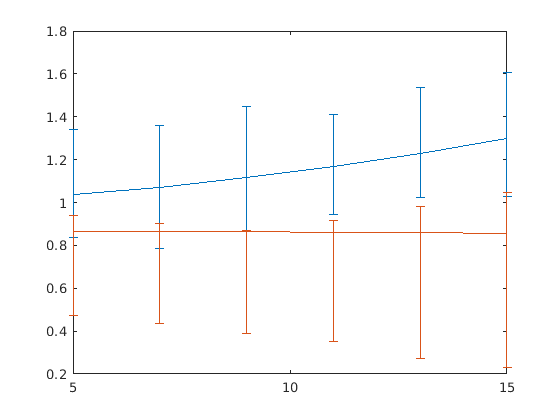

figure;
bw = 5:2:15;
avgNumRelay = [mean(avgNumRelay_1_5), mean(avgNumRelay_1_7), mean(avgNumRelay_1_9), mean(avgNumRelay_1_11), mean(avgNumRelay_1_13), mean(avgNumRelay_1_15)];
avgNumRelayStd = [std(avgNumRelay_1_5), std(avgNumRelay_1_7), std(avgNumRelay_1_9), std(avgNumRelay_1_11), std(avgNumRelay_1_13), std(avgNumRelay_1_15)];
avgNumRelayMin = avgNumRelay - [min(avgNumRelay_1_5), min(avgNumRelay_1_7), min(avgNumRelay_1_9), min(avgNumRelay_1_11), min(avgNumRelay_1_13), min(avgNumRelay_1_15)];
avgNumRelayMax = [max(avgNumRelay_1_5), max(avgNumRelay_1_7), max(avgNumRelay_1_9), max(avgNumRelay_1_11), max(avgNumRelay_1_13), max(avgNumRelay_1_15)] - avgNumRelay;
errorbar(bw,avgNumRelay,avgNumRelayMin,avgNumRelayMax); hold on;
avgNumRelayIdp = [mean(avgNumRelay_1_5_idp), mean(avgNumRelay_1_7_idp), mean(avgNumRelay_1_9_idp), mean(avgNumRelay_1_11_idp), mean(avgNumRelay_1_13_idp), mean(avgNumRelay_1_15_idp)];
avgNumRelayIdpStd = [std(avgNumRelay_1_5_idp), std(avgNumRelay_1_7_idp), std(avgNumRelay_1_9_idp), std(avgNumRelay_1_11_idp), std(avgNumRelay_1_13_idp), std(avgNumRelay_1_15_idp)];
avgNumRelayMinIdp = avgNumRelay - [min(avgNumRelay_1_5_idp), min(avgNumRelay_1_7_idp), min(avgNumRelay_1_9_idp), min(avgNumRelay_1_11_idp), min(avgNumRelay_1_13_idp), min(avgNumRelay_1_15_idp)];
avgNumRelayMaxIdp = [max(avgNumRelay_1_5_idp), max(avgNumRelay_1_7_idp), max(avgNumRelay_1_9_idp), max(avgNumRelay_1_11_idp), max(avgNumRelay_1_13_idp), max(avgNumRelay_1_15_idp)] - avgNumRelay;
errorbar(bw,avgNumRelayIdp,avgNumRelayMinIdp,avgNumRelayMaxIdp);

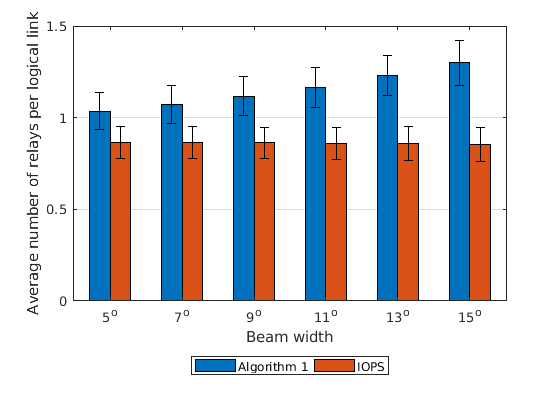

figure;
% Data to be plotted as a bar graph
model_series = [avgNumRelay;avgNumRelayIdp]';
%Data to be plotted as the error bars
model_error = [avgNumRelayStd;avgNumRelayIdpStd]';
% Creating axes and the bar graph
ax = axes;
h = bar(model_series,'BarWidth',1);
% Set color for each bar face
% h(1).FaceColor = 'blue';
% h(2).FaceColor = 'yellow';
% Properties of the bar graph as required
ax.YGrid = 'on';
ax.GridLineStyle = '-';
xticks(ax,[1 2 3 4 5 6]);
% Naming each of the bar groups
xticklabels(ax,{ '5^o', '7^o', '9^o', '11^o', '13^o', '15^o'});
% X and Y labels
xlabel ('Beam width');
ylabel ('Average number of relays per logical link');
% Creating a legend and placing it outside the bar plot
lg = legend('Algorithm 1','IOPS','AutoUpdate','off');
lg.Location = 'BestOutside';
lg.Orientation = 'Horizontal';
hold on;
% Finding the number of groups and the number of bars in each group
ngroups = size(model_series, 1);
nbars = size(model_series, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
for i = 1:nbars
    % Calculate center of each bar
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    errorbar(x, model_series(:,i), model_error(:,i), 'k', 'linestyle', 'none');
end

numRelay_2_5 = zeros(length(name_2_5),1);
numRelay_2_7 = zeros(length(name_2_7),1);
numRelay_2_9 = zeros(length(name_2_9),1);
numRelay_2_11 = zeros(length(name_2_11),1);
numRelay_2_13 = zeros(length(name_2_13),1);
numRelay_2_15 = zeros(length(name_2_15),1);
numRelay_2_5_idp = zeros(length(name_2_5),1);
numRelay_2_7_idp = zeros(length(name_2_7),1);
numRelay_2_9_idp = zeros(length(name_2_9),1);
numRelay_2_11_idp = zeros(length(name_2_11),1);
numRelay_2_13_idp = zeros(length(name_2_13),1);
numRelay_2_15_idp = zeros(length(name_2_15),1);
for i = 1:length(name_2_5)
    filename = pathname + name_2_5(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_5(i)]);
    numRelay_2_5(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_2_5(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_5(i)]);
    numRelay_2_5_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_2_7)
    filename = pathname + name_2_7(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_7(i)]);
    numRelay_2_7(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_2_7(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_7(i)]);
    numRelay_2_7_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_2_9)
    filename = pathname + name_2_9(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
    numRelay_2_9(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_2_9(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
    numRelay_2_9_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_2_11)
    filename = pathname + name_2_11(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_11(i)]);
    numRelay_2_11(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_2_11(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_11(i)]);
    numRelay_2_11_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_2_13)
    filename = pathname + name_2_13(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_13(i)]);
    numRelay_2_13(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_2_13(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_13(i)]);
    numRelay_2_13_idp(i) = data(2,end);
    fclose(fileID);
end
for i = 1:length(name_2_15)
    filename = pathname + name_2_15(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_15(i)]);
    numRelay_2_15(i) = data(2,end);
    fclose(fileID);
    filename = pathnameidp + name_2_15(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_15(i)]);
    numRelay_2_15_idp(i) = data(2,end);
    fclose(fileID);
end

avgNumRelay_2_5 = numRelay_2_5./pathNum_name_2_5; mean(avgNumRelay_2_5)

ans = 0.9375

avgNumRelay_2_5_idp = numRelay_2_5_idp./pathNum_name_2_5; mean(avgNumRelay_2_5_idp)

ans = 0.8077

avgNumRelay_2_7 = numRelay_2_7./pathNum_name_2_7; mean(avgNumRelay_2_7)

ans = 0.9712

avgNumRelay_2_7_idp = numRelay_2_7_idp./pathNum_name_2_7; mean(avgNumRelay_2_7_idp)

ans = 0.8076

avgNumRelay_2_9 = numRelay_2_9./pathNum_name_2_9; mean(avgNumRelay_2_9)

ans = 0.9911

avgNumRelay_2_9_idp = numRelay_2_9_idp./pathNum_name_2_9; mean(avgNumRelay_2_9_idp)

ans = 0.8035

avgNumRelay_2_11 = numRelay_2_11./pathNum_name_2_11; mean(avgNumRelay_2_11)

ans = 1.0422

avgNumRelay_2_11_idp = numRelay_2_11_idp./pathNum_name_2_11; mean(avgNumRelay_2_11_idp)

ans = 0.8158

avgNumRelay_2_13 = numRelay_2_13./pathNum_name_2_13; mean(avgNumRelay_2_13)

ans = 1.0765

avgNumRelay_2_13_idp = numRelay_2_13_idp./pathNum_name_2_13; mean(avgNumRelay_2_13_idp)

ans = 0.8144

avgNumRelay_2_15 = numRelay_2_15./pathNum_name_2_15; mean(avgNumRelay_2_15)

ans = 1.1666

avgNumRelay_2_15_idp = numRelay_2_15_idp./pathNum_name_2_15; mean(avgNumRelay_2_15_idp)

ans = 0.8275

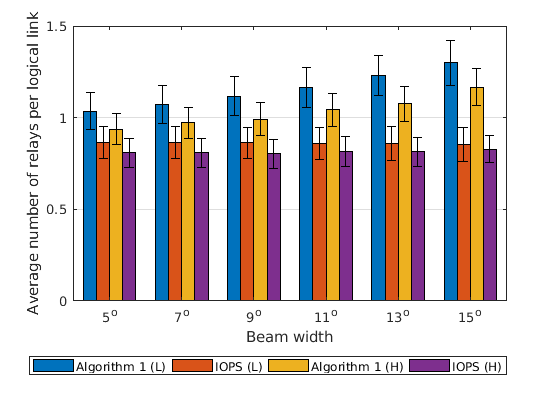

bw = 5:2:15;
avgNumRelay2 = [mean(avgNumRelay_2_5), mean(avgNumRelay_2_7), mean(avgNumRelay_2_9), mean(avgNumRelay_2_11), mean(avgNumRelay_2_13), mean(avgNumRelay_2_15)];
avgNumRelayStd2 = [std(avgNumRelay_2_5), std(avgNumRelay_2_7), std(avgNumRelay_2_9), std(avgNumRelay_2_11), std(avgNumRelay_2_13), std(avgNumRelay_2_15)];
avgNumRelayMin = avgNumRelay - [min(avgNumRelay_2_5), min(avgNumRelay_2_7), min(avgNumRelay_2_9), min(avgNumRelay_2_11), min(avgNumRelay_2_13), min(avgNumRelay_2_15)];
avgNumRelayMax = [max(avgNumRelay_2_5), max(avgNumRelay_2_7), max(avgNumRelay_2_9), max(avgNumRelay_2_11), max(avgNumRelay_2_13), max(avgNumRelay_2_15)] - avgNumRelay;
% errorbar(bw,avgNumRelay,avgNumRelayMin,avgNumRelayMax); hold on;
avgNumRelayIdp2 = [mean(avgNumRelay_2_5_idp), mean(avgNumRelay_2_7_idp), mean(avgNumRelay_2_9_idp), mean(avgNumRelay_2_11_idp), mean(avgNumRelay_2_13_idp), mean(avgNumRelay_2_15_idp)];
avgNumRelayIdpStd2 = [std(avgNumRelay_2_5_idp), std(avgNumRelay_2_7_idp), std(avgNumRelay_2_9_idp), std(avgNumRelay_2_11_idp), std(avgNumRelay_2_13_idp), std(avgNumRelay_2_15_idp)];
avgNumRelayMinIdp = avgNumRelay - [min(avgNumRelay_2_5_idp), min(avgNumRelay_2_7_idp), min(avgNumRelay_2_9_idp), min(avgNumRelay_2_11_idp), min(avgNumRelay_2_13_idp), min(avgNumRelay_2_15_idp)];
avgNumRelayMaxIdp = [max(avgNumRelay_2_5_idp), max(avgNumRelay_2_7_idp), max(avgNumRelay_2_9_idp), max(avgNumRelay_2_11_idp), max(avgNumRelay_2_13_idp), max(avgNumRelay_2_15_idp)] - avgNumRelay;
% errorbar(bw,avgNumRelayIdp,avgNumRelayMinIdp,avgNumRelayMaxIdp);
figure;
% Data to be plotted as a bar graph
model_series = [avgNumRelay;avgNumRelayIdp;avgNumRelay2;avgNumRelayIdp2]';
%Data to be plotted as the error bars
model_error = [avgNumRelayStd;avgNumRelayIdpStd;avgNumRelayStd2;avgNumRelayIdpStd2]';
% Creating axes and the bar graph
ax = axes;
h = bar(model_series,'BarWidth',1);
% Set color for each bar face
% h(1).FaceColor = 'blue';
% h(2).FaceColor = 'yellow';
% Properties of the bar graph as required
ax.YGrid = 'on';
ax.GridLineStyle = '-';
xticks(ax,[1 2 3 4 5 6]);
% Naming each of the bar groups
xticklabels(ax,{ '5^o', '7^o', '9^o', '11^o', '13^o', '15^o'});
% X and Y labels
xlabel ('Beam width');
ylabel ('Average number of relays per logical link');
% Creating a legend and placing it outside the bar plot
lg = legend('Algorithm 1 (L)','IOPS (L)','Algorithm 1 (H)','IOPS (H)','AutoUpdate','off');
lg.Location = 'BestOutside';
lg.Orientation = 'Horizontal';
hold on;
% Finding the number of groups and the number of bars in each group
ngroups = size(model_series, 1);
nbars = size(model_series, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
for i = 1:nbars
    % Calculate center of each bar
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    errorbar(x, model_series(:,i), model_error(:,i), 'k', 'linestyle', 'none');
end

## Collect the non-line of sight logical links

All cases which have feasible solutions are recorded in "name_1_5"

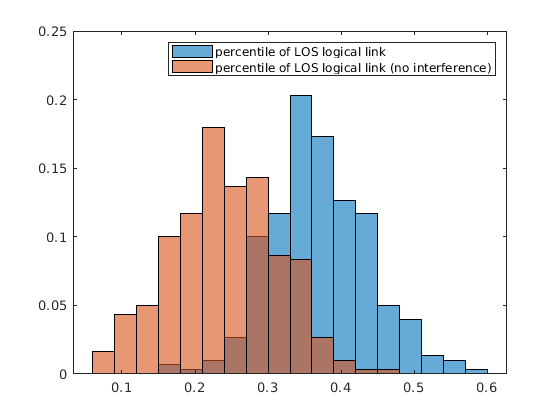

fileID = fopen('../../Data/Number_LOS_Links/Data_NumLOSLinks_2.txt','r');
data = fscanf(fileID,'%d %d',[4,Inf]);
percentileLOSLinks = data(2,:)./data(4,:);
percentileLOSLinks_noInt = (data(2,:)-data(3,:))./data(4,:);
figure;
histogram(percentileLOSLinks,'Normalization','probability'); hold on;
histogram(percentileLOSLinks_noInt,'Normalization','probability');
legend('percentile of LOS logical link', 'percentile of LOS logical link (no interference)');



% numLOSLinks = zeros(length(name_1_5),1);
% numLOSLinks_idp = zeros(length(name_1_5),1);
% for i = 1:length(name_1_5)
%     filename = pathname + name_1_5(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_5(i)]);
%     numRelay_1_5(i) = data(2,end);
%     numLOSLinks(i) = sum(data(2,:)==0);
%     fclose(fileID);
%     filename = pathnameidp + name_1_5(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data_idp = fscanf(fileID,'%d %d',[2,pathNum_name_1_5(i)]);
%     numRelay_1_5_idp(i) = data_idp(2,end);
%     fclose(fileID);
%     numLOSLinks_idp(i) = sum(data_idp(2,:)==0);
% end
% percentileLOSLinks = numLOSLinks./pathNum_name_1_5;
% percentileLOSLinks_idp = numLOSLinks_idp./pathNum_name_1_5;
% meanPerLOSLinks = mean(percentileLOSLinks);
% stdPerLOSLinks = std(percentileLOSLinks);
% figure;
% histogram(percentileLOSLinks)


% figure;
% % Data to be plotted as a bar graph
% model_series = [avgNumRelay;avgNumRelayIdp;avgNumRelay2;avgNumRelayIdp2]';
% %Data to be plotted as the error bars
% model_error = [avgNumRelayStd;avgNumRelayIdpStd;avgNumRelayStd2;avgNumRelayIdpStd2]';
% % Creating axes and the bar graph
% ax = axes;
% h = bar(model_series,'BarWidth',1);
% % Set color for each bar face
% % h(1).FaceColor = 'blue';
% % h(2).FaceColor = 'yellow';
% % Properties of the bar graph as required
% ax.YGrid = 'on';
% ax.GridLineStyle = '-';
% xticks(ax,[1 2 3 4 5 6]);
% % Naming each of the bar groups
% xticklabels(ax,{ '5^o', '7^o', '9^o', '11^o', '13^o', '15^o'});
% % X and Y labels
% xlabel ('Beam width');
% ylabel ('Average number of relays per logical link');
% % Creating a legend and placing it outside the bar plot
% lg = legend('Algorithm 1 (L)','IOPS (L)','Algorithm 1 (H)','IOPS (H)','AutoUpdate','off');
% lg.Location = 'BestOutside';
% lg.Orientation = 'Horizontal';
% hold on;
% % Finding the number of groups and the number of bars in each group
% ngroups = size(model_series, 1);
% nbars = size(model_series, 2);
% % Calculating the width for each bar group
% groupwidth = min(0.8, nbars/(nbars + 1.5));
% % Set the position of each error bar in the centre of the main bar
% % Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
% for i = 1:nbars
%     % Calculate center of each bar
%     x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
%     errorbar(x, model_series(:,i), model_error(:,i), 'k', 'linestyle', 'none');
% end